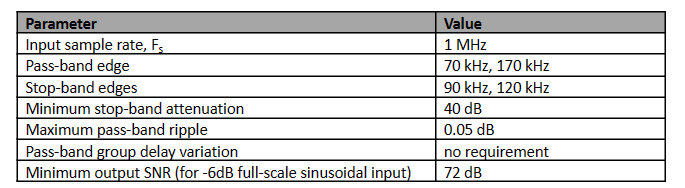

fs = 1e6
fp1 = 70e3;
fp2 = 170e3;
fs1 = 90e3;
fs2 = 120e3;
Atten = 40
PBRipple = 0.05
SNR = 72

wp1 = 2*fp1/fs
wp1 = wp1 * pi;

wp2 = 2*fp2/fs
wp2 = wp2 * pi;

ws1 = 2*fs1/fs
ws1 = ws1 * pi;

ws2 = 2*fs2/fs
ws2 = ws2 * pi;


Low Pass Filter


wc = 0.1 *pi; %arbitrary
lambda=(cos((wp2+wp1)/2))/(cos((wp2-wp1)/2))

% % BandPass
% wp1 = 0.46*pi
% wp2 = 0.66*pi
% ws1 = 0.31*pi
% ws2 = 0.76*pi
% p = cot((wp2-wp1)/2)*tan(wc/2)
% w_hat = ws2
% w = abs(2*atan(-1*p*(lambda - cos(w_hat))/sin(w_hat)))/pi

%% BandStop
p = tan((wp2-wp1)/2)*tan(wc/2)
ws1_hat = abs(2*atan(p*sin(ws1)/(cos(ws1)-lambda)))/pi
ws1_hat = ws1_hat *pi;
ws2_hat = abs(2*atan(p*sin(ws2)/(cos(ws2)-lambda)))/pi
ws2_hat = ws2_hat *pi;

%% chose more stringent stopband freq
if ws1<ws2
    ws_hat = ws1_hat;
else
    ws_hat = ws2_hat;
end

wp_hat = wc

%%prewarp
omega_p = tan(wp_hat/2)
omega_s = tan(ws_hat/2)



syms x
eqn = 20*log10(sqrt(1+x^2)) == PBRipple;
epsilon = double(solve(eqn));
epsilon = epsilon(1)
eqn = 20*log10(x) == Atten;
A = double(solve(eqn))

k = omega_p/omega_s
k1 = epsilon/(sqrt(A^2-1))
k1 = k1(1)
N = acosh(1/k1)/acosh(1/k); %minimum order number
N = ceil(N)

%doesnt consider attenuation, only epsilon (passband ripple)
%will use [z,p,k] = cheb1ap(10,6);
alpha = 1/epsilon + sqrt(1+1/epsilon^2)
a = (alpha^(1/N) - alpha^(-1/N))/2
b = (alpha^(1/N) + alpha^(-1/N))/2

%use iirlp2bs to create digital transform, not formulas
%needs analog filter a and b - use [z,p,k] = cheb1ap(10,6);
% refer to bilinear ellip example for poles and zeroes

fc = 100e3 %arbitrary

fc = 100000

fs = 1e6

fs = 1000000


wt = [wp1/pi wp2/pi]

wt =     0.1400    0.3400


wo = fc/(fs/2) %what should this be?

wo = 0.2000


order = N

order = 6

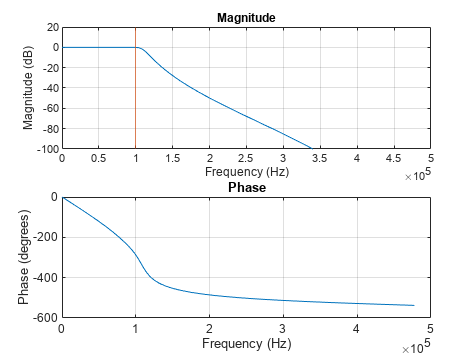

[b,a] = cheby1(order,PBRipple,wo);
freqz(b,a,[],fs)

bq = a2dT(b,5); aq = a2dT(a,5);

xline(fc,Color=[0.8500 0.3250 0.0980])
subplot(2,1,1)
ylim([-100 20])


[num,den] = iirlp2bs(b,a,wo,wt);
hfvt = fvtool(b,a,num,den);
legend(hfvt,"Prototype Filter (TF Form)",...
    "Transformed Bandstop Filter")

syms x
SNR = 72

SNR = 72

eqn = -6 - 20*log10(x) == 72;
Noise = double(solve(eqn))

Noise = 1.2589e-04

eqn = 20*log10(x) == -6;
Signal = double(solve(eqn))

Signal = 0.5012


%9.5.4  Propagation of Input Qunatization Noise to Digital Filter Output
%9.5.5  Algebraic Computation of Output Noise Variance
%9.5.6 Computation of Output Noise Variance using MATLAB
% num = [0.06891975 0.13808186 0.18636107 0.13808186 0.068218751]
% den = [1.0 -1.30613249 1.48301305 -0.77709026 0.2361457]
[r,p,K] = residue(num,den)

r =    0.0256 + 0.0046i
   0.0256 - 0.0046i
   0.0092 + 0.0487i
   0.0092 - 0.0487i
  -0.0745 + 0.0747i
  -0.0745 - 0.0747i
   0.1762 - 0.1101i
   0.1762 + 0.1101i
  -0.1281 - 0.3397i
  -0.1281 + 0.3397i


p =    0.8776 + 0.4314i
   0.8776 - 0.4314i
   0.4909 + 0.8220i
   0.4909 - 0.8220i
   0.8375 + 0.3719i
   0.8375 - 0.3719i
   0.3848 + 0.7323i
   0.3848 - 0.7323i
   0.7297 + 0.2369i
   0.7297 - 0.2369i


K = 0.2566

R = size(r,1);
R2 = size(K,1);
    if R2 > 1
        disp('Cannot continue...')
        return;
    end

    if R2 == 1
        nvar = K^2;
    else
        nvar = 0;
    end

for k = 1:R
    for m = 1:R
        integral = r(k)*conj(r(m))/(1-p(k)*conj(p(m)));
        nvar = nvar+integral;
    end
end
disp('Output Noise Variance = '); disp(real(nvar))

Output Noise Variance = 
    0.8168



ov = nvar

ov = 0.8168 - 0.0000i


%Program 9.5
%Computation of Approximate Output Round-off Noise
x= 1;
order = max(length(num),length(den))-1

order = 12

zi = [zeros(1,order)]

zi =      0     0     0     0     0     0     0     0     0     0     0     0


varnew = 0; k = 1;
while k > 0.000001
    [y,zf] = filter(num,den,x,zi);
    zi = zf;
    varold = varnew;
    varnew = varnew + abs(y)*abs(y);
    k = varnew - varold;
    x = 0;
end
disp('Output Noise Variance = '); disp(real(varnew))

Output Noise Variance = 
    0.8069

